## Extract App Graphs using Map Reduce

An optimized version of muBench Alibaba Example Script, utilizing parallelism to handle larger input data

[https://de.mathworks.com/help/matlab/ref/mapreduce.html](https://de.mathworks.com/help/matlab/ref/mapreduce.html)

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Load Config

Then run this snippet  to load your choices.

[trace_header, trace_formats, trace_vartypes] = constants();
[trace_location, trace_header_lines, output_dir_sequential, output_dir_parallel, output_dir_root, sampling_factor] = config();

### Prepare selected columns

We may not care about certain columns, once we fully understand the trace data.

ignore_columns = ["response_time"];
used_col_idx = ~ismember(trace_header, ignore_columns);
trace_selected_cols = trace_header(used_col_idx);
trace_selected_vartypes = trace_vartypes(used_col_idx);
trace_selected_formats = trace_formats(used_col_idx);

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedFormats", trace_selected_formats, ...
    "SelectedVariableNames", trace_selected_cols);
preview(ds)

ans = 8×10 table
    timestamp        trace_id             service              rpc_id          rpc_type    upstream_ms       upstream_instance        interface       downstream_ms     downstream_instance 
    _________    _________________    _______________    __________________    ________    ____________    _____________________    ______________    _____________    _____________________

     115352      {'T_11560863075'}    {'S_153587416'}    {'0.1'           }    {'rpc' }    {'MS_58845'}    {'MS_58845_POD_0'   }    {'xOuy6-80Vt'}    {'MS_71712'}     {'MS_71712_POD_244' }
      86450      {'T_22121589080'}    {'S_1798353'  }    {'0.1'           }

### Map Reduce to find valid trace ids

This section filters out invalid traces

Invalidation Criteria:

- interface, upstream_ms or downstream_ms is "UNKNOWN" or "UNAVAILABLE"

- The rpc_id parent of an entry of one trace_id is not present

- An entry of one trace_id is not connected to the "USER" upstream entry

col_idx_trace_id = strcmp(trace_header, "trace_id") > 0;
% wrap mapper function to pass variable context
mapFunc = @(a, b, c)trace_mapper(a, b, c, col_idx_trace_id);
% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)trace_reducer(a, b, c, empty_table);
tic
trace_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results');

Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map   2% Reduce   0%
Map   4% Reduce   0%
Map   6% Reduce   0%
Map   9% Reduce   0%
Map  11% Reduce   0%
Map  13% Reduce   0%
Map  15% Reduce   0%
Map  18% Reduce   0%
Map  20% Reduce   0%
Map  22% Reduce   0%
Map  25% Reduce   0%
Map  27% Reduce   0%
Map  29% Reduce   0%
Map  31% Reduce   0%
Map  34% Reduce   0%
Map  36% Reduce   0%
Map  38% Reduce   0%
Map  40% Reduce   0%
Map  43% Reduce   0%
Map  45% Reduce   0%
Map  47% Reduce   0%
Map  50% Reduce   0%
Map  52% Reduce   0%
Map  54% Reduce   0%
Map  56% Reduce   0%
Map  59% Reduce   0%
Map  61% Reduce   0%
Map  63% Reduce   0%
Map  65% Reduce   0%
Map  68% Reduce   0%
Map  70% Reduce   0%
Map  72% Reduce   0%
Map  75% Reduce   0%
Map  77% Reduce   0%
Map  79% Reduce   0%
Map  81% Reduce   0%
Map  84% Reduce   0%
Map  86% Reduce   0%
Map  88% Reduce   0%
Map  90% R

toc

Elapsed time is 2919.122364 seconds.


clear empty_table;
clear col_idx_trace_id;
clear mapFunc;
clear reduceFunc;

### Data Example

Optional: Gives a preview of the data.

prev_trace_ds = copy(trace_ds);
reset(prev_trace_ds);
trace_prev_ds.ReadSize = 10;
prev_trace_data = read(prev_trace_ds);
prev_trace_data.Value{:,1}

ans = 2×10 table
    timestamp       trace_id          service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance
    _________    _______________    ____________    ______    ________    ___________    _________________    ____________    _____________    ___________________

     112214      "T_10000571621"    "S_94914028"    "0"        "http"     "USER"         "USER"               "0o4U3dcdXl"     "MS_45367"      "MS_45367_POD_9"   
     112214      "T_10000571621"    "S_94914028"    "0.1"      "rpc"      "MS_45367"     "MS_45367_POD_9"     "V-8EC_v-NS"     "MS_45753"      "MS_45753_

### Map Reduce to services

This section filters out invalid traces and stores the resulting trace entries grouped by service

col_idx_service = strcmp(trace_header, "service") > 0;
% wrap mapper function to pass variable context
mapFunc = @(a, b, c)service_mapper(a, b, c, col_idx_service);
% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)service_reducer(a, b, c, empty_table);
tic
service_ds = mapreduce(trace_ds, mapFunc, reduceFunc, 'OutputFolder', './results');

Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map   1% Reduce   0%
Map   2% Reduce   0%
Map   3% Reduce   0%
Map   4% Reduce   0%
Map   5% Reduce   0%
Map   6% Reduce   0%
Map   7% Reduce   0%
Map   8% Reduce   0%
Map   9% Reduce   0%
Map  10% Reduce   0%
Map  11% Reduce   0%
Map  12% Reduce   0%
Map  13% Reduce   0%
Map  14% Reduce   0%
Map  15% Reduce   0%
Map  16% Reduce   0%
Map  17% Reduce   0%
Map  18% Reduce   0%
Map  19% Reduce   0%
Map  20% Reduce   0%
Map  21% Reduce   0%
Map  22% Reduce   0%
Map  23% Reduce   0%
Map  24% Reduce   0%
Map  25% Reduce   0%
Map  26% Reduce   0%
Map  27% Reduce   0%
Map  28% Reduce   0%
Map  29% Reduce   0%
Map  30% Reduce   0%
Map  31% Reduce   0%
Map  32% Reduce   0%
Map  33% Reduce   0%
Map  34% Reduce   0%
Map  35% Reduce   0%
Map  36% Reduce   0%
Map  37% Reduce   0%
Map  38% Reduce   0%
Map  39% Reduce   0%
Map  40% R

toc

Elapsed time is 11756.839079 seconds.


clear empty_table;
clear col_idx_service;
clear mapFunc;
clear reduceFunc;

### Data Example

Optional: Gives a preview of the data.

prev_svc_ds = copy(service_ds);
reset(prev_svc_ds);
prev_svc_ds.ReadSize = 10;
prev_svc_data = read(prev_svc_ds);
prev_svc_data.Value{:,1}

ans = 1×10 table
    timestamp       trace_id          service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance
    _________    ______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ___________________

     163326      "T_9539295156"    "S_100054096"     "0"       "http"       "USER"            "USER"          "mvVvHKKLKz"     "MS_37575"       "MS_37575_POD_91" 


ans = 1×10 table
    timestamp       trace_id          service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance
    _________    ______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ___________________

      30674      "T_6375803444"    "S_100180625"     "0"       "http"       "USER"            "USER"          "Yfe0eSm3uP"     "MS_41385"      "MS_41385_POD_379" 


ans = 1×10 table
    timestamp       trace_id           service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance 
    _________    _______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ____________________

      19391      "T_16535434930"    "S_100307481"     "0"       "http"       "USER"            "USER"          "-6DoCTHBGa"     "MS_15934"      "MS_15934_POD_88740"


ans = 1×10 table
    timestamp       trace_id           service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance 
    _________    _______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ____________________

      37869      "T_21894850494"    "S_100307662"     "0"       "http"       "USER"            "USER"          "rs62q8KsFg"     "MS_15934"      "MS_15934_POD_50160"


ans = 1×10 table
    timestamp       trace_id          service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms     downstream_instance 
    _________    ______________    _____________    ______    ________    ___________    _________________    ____________    _____________    _____________________

      71556      "T_8199583809"    "S_100307781"     "0"       "http"       "USER"            "USER"          "kodj6aKvBj"     "MS_15934"      "MS_15934_POD_167588"


ans = 1×10 table
    timestamp       trace_id          service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance
    _________    ______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ___________________

      42006      "T_2058728916"    "S_100308466"     "0"       "http"       "USER"            "USER"          "9RVfGWw4IL"     "MS_39562"       "MS_39562_POD_3"  


ans = 1×10 table
    timestamp       trace_id           service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance
    _________    _______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ___________________

     107093      "T_24757635992"    "S_100308898"     "0"       "http"       "USER"            "USER"          "I7RNBd2JI0"     "MS_17117"      "MS_17117_POD_3250"


ans = 2×10 table
    timestamp       trace_id           service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance 
    _________    _______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ____________________

     168019      "T_14922105947"    "S_100309591"     "0"       "http"       "USER"            "USER"          "CQMERKX9Sz"     "MS_15934"      "MS_15934_POD_29886"
       9262      "T_24574415544"    "S_100309591"     "0"       "http"       "USER"            "USER"          "CQMERKX9Sz"     "MS_15934"      "MS

ans = 1×10 table
    timestamp       trace_id           service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms     downstream_instance 
    _________    _______________    _____________    ______    ________    ___________    _________________    ____________    _____________    _____________________

     170668      "T_14975062109"    "S_100310711"     "0"       "http"       "USER"            "USER"          "x2UMHh2-zs"     "MS_15934"      "MS_15934_POD_128247"


ans = 1×10 table
    timestamp       trace_id           service       rpc_id    rpc_type    upstream_ms    upstream_instance     interface      downstream_ms    downstream_instance
    _________    _______________    _____________    ______    ________    ___________    _________________    ____________    _____________    ___________________

      81835      "T_12999403509"    "S_100310781"     "0"       "http"       "USER"            "USER"          "By9rqkZ5cl"     "MS_18249"      "MS_18249_POD_7108"


### Service Graphs

Create directed graphs from the trace entries related to a specific service.

tic
service_graph_ds = mapreduce(service_ds, @service_graph_mapper, @service_graph_reducer, 'OutputFolder', './results');

Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
WARN: Has more than one service after 'USER' ->
    "MS_71990"
    "MS_34532"

Using only first entry.
WARN: Has more than one service after 'USER' ->
    "MS_53154"
    "MS_15284"

Using only first entry.
WARN: Has more than one service after 'USER' ->
    "MS_61776"
    "MS_19492"

Using only first entry.
WARN: Has more than one service after 'USER' ->
    "MS_52059"
    "MS_3386"

Using only first entry.
WARN: Has more than one service after 'USER' ->
    "MS_15284"
    "MS_53154"

Using only first entry.
WARN: Has more th

toc

### Port dataformat

From MapReduce KeyValueDatastore output to serial processing

(we leave the map-reduce environment and process classically)

service_graphs = readall(service_graph_ds);

### Prepare Input

Prepare input data to be a nicely accessible table

% Flatten service_graphs.Value into a table with 3 columns
value_as_table = cell2table(service_graphs.Value);
flattened_values = cell2table(value_as_table{:,1});
services = [service_graphs.Key flattened_values];
% Label Columns
services.Properties.VariableNames(1) = "service_id";
services.Properties.VariableNames(2) = "graph";
services.Properties.VariableNames(3) = "possible_node_names";
services.Properties.VariableNames(4) = "ms_count";
services.Properties.VariableNames(5) = "max_depth";
services.Properties.VariableNames(6) = "trace_count";


clear value_as_table;
clear flattened_values;

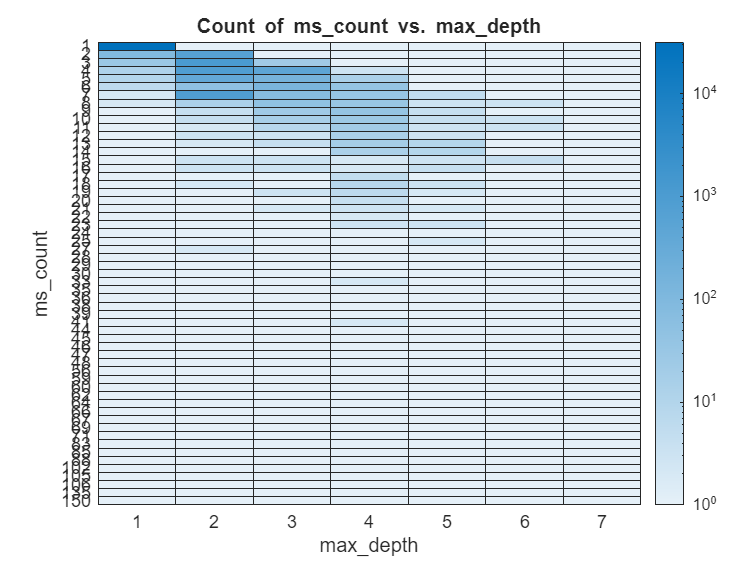

heatmap(services,"max_depth","ms_count","ColorScaling","log");

### Filter Input

About 31500 of the ~37000 services only have a ms_count of 1 (monoliths).

TODO: Would be interesting to see, how many of these are mem-cached (results).

To reduce the computing time for clustering and provide proper scales we split up the input data.

monolith_idx = services.ms_count < 2;
monoliths = services(monolith_idx,:);
microservices = services(~monolith_idx,:);

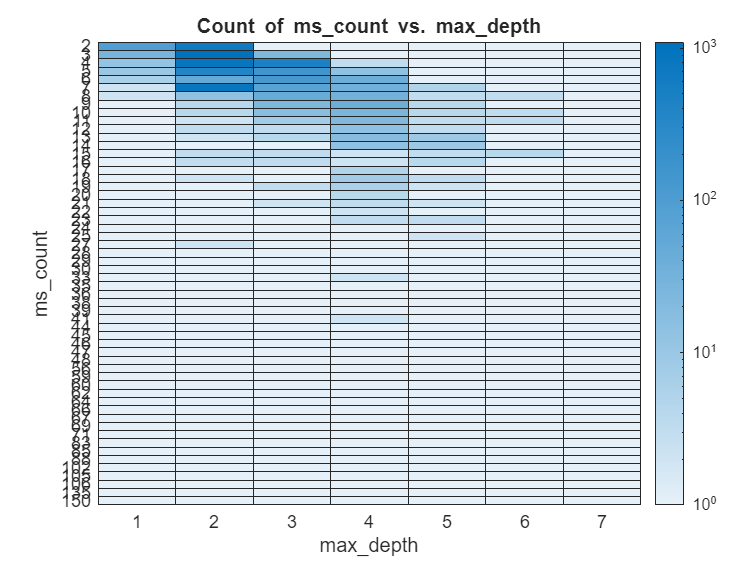

heatmap(microservices,"max_depth","ms_count","ColorScaling","log");

byMSCount = groupsummary(service_clusters,"ms_count")

byMSCount = 57×2 table
    ms_count    GroupCount
    ________    __________

        1         31581   
        2           719   
        3          1143   
        4          1328   
        5           543   
        6           220   
        7           957   
        8           101   
        9            70   
       10            54   
       11            37   
       12            24   
       13            33   
       14            25   
       15            15   
       16            13   


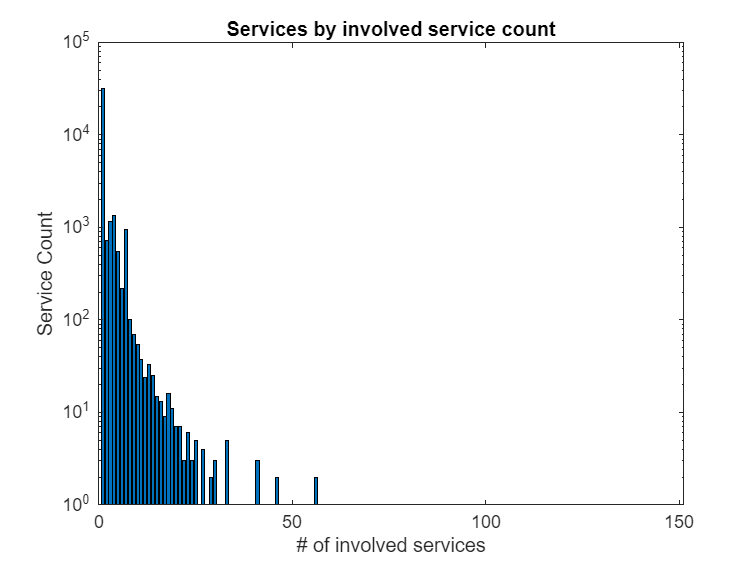

bar(byMSCount.ms_count, byMSCount.GroupCount);
title("Services by involved service count");
yscale log;
ylabel("Service Count");
xlabel("# of involved services");

### Create 30 clusters

We inspect the found service graphs for similarity and cluster them into 30 parts.

We will treat all monoliths as one cluster and the microservices share the other 29 clusters.

#### Cluster microservices

ms_cluster_count = 29;
limit = height(microservices);
% limit = 1000;
tic
[microservice_clusters] = service_clustering(microservices(1:limit,:),0.2,ms_cluster_count);

Out of memory. The likely cause is an infinite recursion within the program.

Error in digraph/validateNodeID (line 613)
                    src = findnode(G, s);

toc
clear ms_cluster_count;
clear limit;

#### Prepare and append monolith data

% Create output table
monolith_cluster_nr = ones(height(monoliths),1) + ms_cluster_count;
monolith_clusters = [monoliths table(monolith_cluster_nr)];
% Label Columns
monolith_clusters.Properties.VariableNames(width(monolith_clusters)) = "cluster";

clear monolith_cluster_nr;

Combine microservices and monolith clusters

service_clusters = [microservice_clusters; monolith_clusters];

clear microservice_clusters;
clear monolith_clusters;

### Inspect depth and ms count by cluster

meansByCluster = groupsummary(service_clusters,"cluster","mean",["max_depth","ms_count"])

meansByCluster = 30×4 table
    cluster    GroupCount    mean_max_depth    mean_ms_count
    _______    __________    ______________    _____________

       1          3579            2.356           4.9573    
       2            13           3.3846           7.0769    
       3             3                3                6    
       4            32           2.9375             5.25    
       5            42           2.0952           5.1429    
       6           411           2.0024           3.6496    
       7            41           3.0244            4.878    
       8             2                4              5.5    
       9           832                2           6.9952    
      10            51           4.5294           14.392    
      11             4             2.75                7    
      12             3                3   

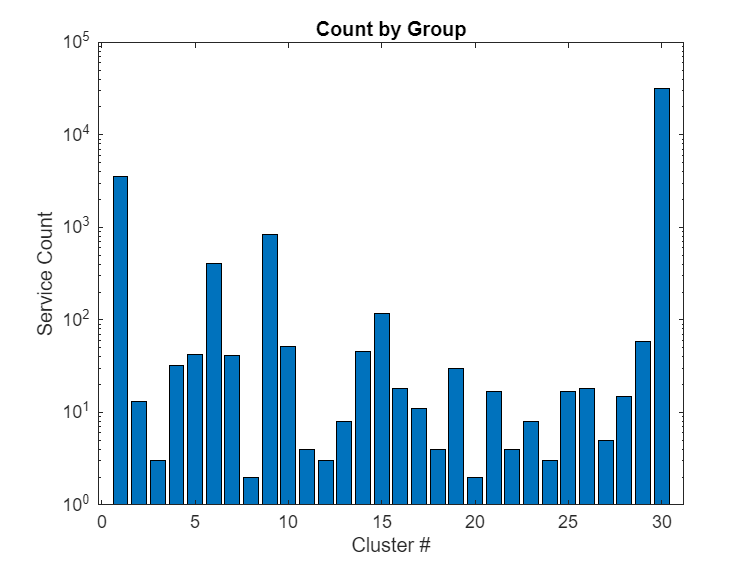

bar(meansByCluster.cluster, meansByCluster.GroupCount)
title("Count by Group");
yscale log;
ylabel("Service Count");
xlabel("Cluster #");

### Sample services

Extract a sample of % services, as we do not want to deploy 38k services.

Workload with muBench is mainly generated through requests, so we do not only have a choice of "which services", but also "how many requests for the selected services"

[service_samples] = service_sampling(service_clusters, sampling_factor)

service_samples = 393×6 table
      service_id       ms_count    max_depth    cluster    service_cluster_share    trace_factor
    _______________    ________    _________    _______    _____________________    ____________

    {'S_130831269'}       27           2           1               0.99391            0.047472  
    {'S_30850351' }        6           1           1             0.0026603            0.047472  
    {'S_107380679'}        3           1           1            0.00082266            0.047472  
    {'S_48222319' }        5           2           1            0.00058761            0.047472  
    {'S_99680464' }        4           3           1            0.00041667            0.047472  
    {'S_75760745' }        2           2           1            0.00025641            

### App Graphs

Construct graphs for each app (cluster)

% needs adaptation
% [apps] = cluster_graphs(service_clusters);